# Homework 4: Engineering color

### *Converting reflectance spectra to percieved color*

*In this demo we will convert reflection spectra to color using the CIE 1931 XYZ color space.*

*This will build on the code you've already developed for the course for 1D photonic crystals. The learning objectives are to*

- *understand how reflectance spectra relates to actual percieved color*

- *recreate the spectra and CIE plots of structural color from previous homework and in literature*

For this demo, please familiarize yourseld with the CIE 1931 XYZ color space. Below some background reading is provided:

"The CIE 1931 XYZ color space (also known as the CIE 1931 color space) was one of the earliest mathematical definitions of color sense and was developed by the International Lighting Corporation in 1931. This system is an RGB system defined since 1931, and it uses three primary colors: red R, green G, and blue B. It is based on a basic theory that mixing the three components is equivalent to a white color, which it counts as a color reference, which has become the source of equal energy, and this is due to the representation The CIE XYZ color space was derived from a set of experiments performed by David Wright and John Guild in 1920. Their experimental results were grouped into a specification of the CIE RGB color space from which the CIE XYZ color space was derived."* From Hussain Ali Badran et al 2021 J. Phys.: Conf. Ser. 1963 012102*

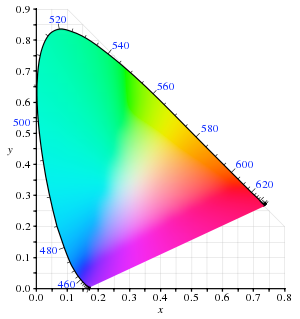

The CIE 1931 XYZ color space (Image courtesy of BenRG via Wikimedia Commons)

"The values of triple stimulation in the CIE 1931 color space are denoted by X, Y, Z. Any special method of linking the triple stimulation values with each color is called (colour space) and the 1931 color space CIE is distinctive because it depends on direct measurements of human visual perception, and it is useful as a rule, other colour spaces are known for them. Since the human eye has three kinds of color sensors that meet various wavelength ranges. Figure 1 shows a color scheme for the CIE 1931 color space, which shows a complete description of all visible colors with a three-dimensional drawing" 

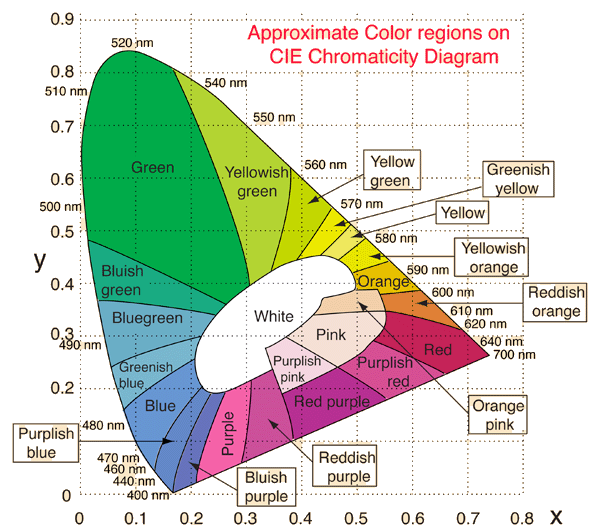

Via [http://hyperphysics.phy-astr.gsu.edu/hbase/vision/cie.html](http://hyperphysics.phy-astr.gsu.edu/hbase/vision/cie.html) 

## Part 0

## Install and test Image Processing Toolbox

In this HW we will take advantage of the MATLAB *plotChromaticity()* function, which provides the chromaticity plot background shown in the above figures. This is a part of the Image Processing Toolbox. Please install this toolbox, test that you can run plotChromaticity(), review the [documentation](https://www.mathworks.com/help/images/ref/plotchromaticity.html), and then plot the MIT official red at defined here [https://web.mit.edu/graphicidentity/colors.html](https://web.mit.edu/graphicidentity/colors.html) in RGB.

% run plotChromaticity() and a CIE plot should appear
plotChromaticity() 

% Convert the official MIT red to CIE coordinates and 
% plot it on the CIE color space

% Define the wavelength range and frequency for the visible spectrum
lambda = linspace(380, 780, 400); % Wavelength in nm [cite: 34, 42]
c = 2.9979e8; % Speed of light
omega = (2 * pi * c) ./ (lambda * 1e-9); % Angular frequency in rad/s

% Official MIT Red (Pantone 201) can be approximated by a specific reflectance.
% For this exercise, we define a target reflectance spectrum R_mit.
% (Note: In a laboratory setting, this would be measured data).
R_mit = zeros(size(lambda));
R_mit(lambda > 600) = 0.9; % Red dominance in the spectrum

% Calculate the CIE x,y coordinates using your implemented findCIE function
% which uses the piecewise Gaussian fits from Equation 4[cite: 95, 96, 101].
[x_mit, y_mit] = findCIE(omega, R_mit);

% Plot the coordinate on the existing CIE color space
hold on;
plot(x_mit, y_mit, 'r*', 'MarkerSize', 10, 'LineWidth', 2);
text(x_mit + 0.01, y_mit, 'Official MIT Red', 'Color', 'r', 'FontSize', 12);
hold off;

% Display the coordinates
fprintf('MIT Red CIE x: %.4f\n', x_mit);

MIT Red CIE x: 0.6861


fprintf('MIT Red CIE y: %.4f\n', y_mit);

MIT Red CIE y: 0.3139


## Part 1 

## Extract the color from reflectance spectra:

Now that you can plot points on a CIE chart using RGB values, you will advance to plotting color from reflectance spectra. Here you will create a function *findCIE.m *which will accept a reflection spectrum (your *R* and *omega *vector variables from homework 3) and output the resulting x,y coordinates for the CIE chromaticity diagram. To properly do this, we need to understand how those points are found from spectra. Using class notes, independent research, and the provided document "Simple Analytic Approximations to the CIE XYZ Color Matching Functions", provide brief answers to the below prompts:

- The color matching functions $\bar{x} \left(\lambda \right),\bar{y} \left(\lambda \right),\textrm{and}\;z\left(\lambda \right)$ represent... 

- X, Y,and Z values are calculated from the color matching functions and the reflection spectra using the expressions:

- X, Y,and Z represent... 

- The x and y chromaticity diagram coordinates are found via the expressions:

### A. Create the findCIE.m function:

*Be sure to reference the provided document "Simple Analytic Approximations to the CIE XYZ Color Matching Functions", *which provides the needed expressions for the color matching functions $\bar{x} \left(\lambda \right),\bar{y} \left(\lambda \right),\textrm{and}\;z\left(\lambda \right)$.

% Fill in the provided findCIE.m function

### B. Extract the color of the bubbles from HW 3

Next, load the sprecta that you output in part 2 of HW 3 for the thin film interference in soap bubbles, call findCIE.m on them, and plot their coordinates on the CIE chart (you should have a point on the CIE chart for each bubble thickness, label each).

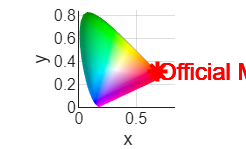

%% Load your bubble data and call your new function findCIE.m on it
% Assuming 'thicknesses' is a vector of the bubble thicknesses from HW3
% and 'R_bubbles' is a matrix where each column is the reflectance spectrum
% for the corresponding thickness.

hold on; % Ensure we plot on the existing CIE chart

% 1. Define the thicknesses you used in HW3 (example values in nm)
thicknesses = [200, 300, 400, 500, 600];
R_bubbles = zeros(length(lambda_nm), length(thicknesses));
% Ensure omega and R_bubbles are defined from the same wavelength linspace
% and that they are both oriented as columns.
for i = 1:length(thicknesses)
    % Pass the i-th column of R_bubbles
    [x_coord, y_coord] = findCIE(omega, R_bubbles(:, i));
    
    % Plotting logic follows...
    plot(x_coord, y_coord, 'ro');
end

Arrays have incompatible sizes for this operation.

Error in findCIE (line 34)
    X = trapz(lambda, R .* x_fit);
    ^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^
Related documentation


title('CIE Coordinates for Soap Bubble Thin-Film Interference');
hold off;


## Part 2 

## Replicating structural color from nature

One of the most famous examples of structural color in nature is the butterfly. Here we will attempt to recreate the nanostructure of a butterflys wing to make our own tunable colored films. 

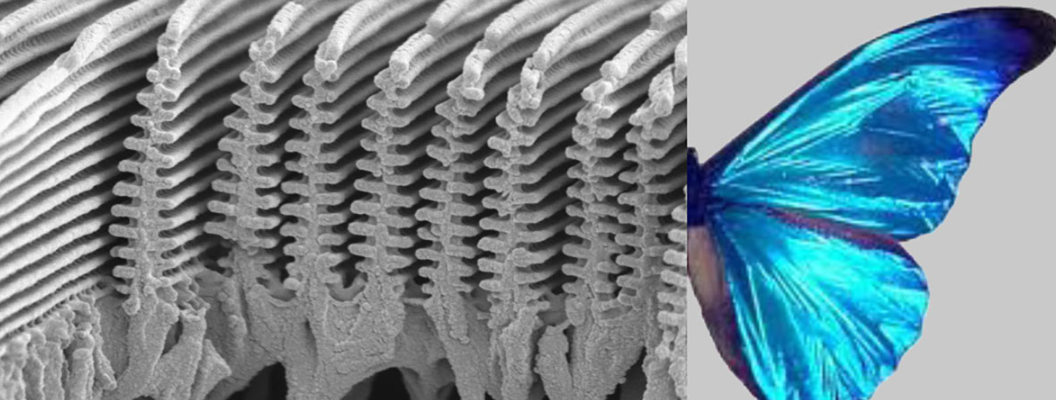

The nanostructure of a butterflys wings, from Cary A Tippets *et al* 2016 *J. Opt.* 18 065105

As you can see in the above picture, the nanostructure of a butterfly's wing is made up of complex, ridged towers and pores. To try to exactly recreate this in the MIT Nano lab would be very complex, expensive, and low throughput. However, we can still take inspiration from the butterfuly while using less complex fabrication techniques, specifically by create mesoporous structures like the one imaged below:

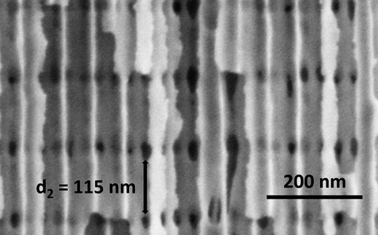

Here, pores are created in alumina in both the perpendicular and transverse direction to the surface, creating a 3D metamaterial. By tuning the periodicity of the pores, the color of the structure is tuned. Thus, the structural color is arrising from Bragg diffraction which you modeled in HW 3. We will model these porous structures as 1D photonic crystals with alternating layers of high ($\left.\varepsilon_1 ,d_1 \right)$ and low ($\left.\varepsilon_2 ,d_2 \right)$ porosity, where the low porosity layer is just the longitudinal pore while the high porisity layer is the intersection of the longitudial and transverse pores. Assume that the high porosity layers are 80% porous $\left(p_1 =0\ldotp 80\right)$ and that the low porosity layers are 65% porous ($p_2 =0\ldotp 65$).

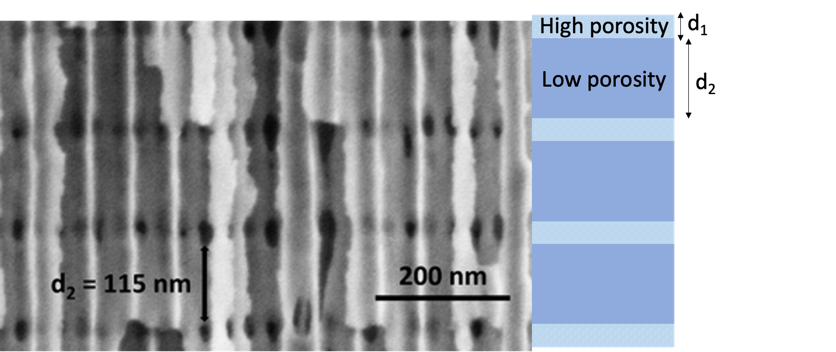

### A. Effective refractive index of porous dielectrics: Maxwell-Garnett equation

To model the porous metamaterial we need the effective refractive index of each layer. First, create a function that accepts the porosity p, ambient permittivity, $\varepsilon_a$, and material permittivity, $\varepsilon_m$, and returns the effective index $\varepsilon_{\textrm{eff}}$ of the material. Assume that any of these inputs could be a vector.

% Fill in the provided maxwellGarnett.m function

Next, plot the effective refractive index $\epsilon_{\textrm{eff}}$ of the porous alumina (${\textrm{Al}}_2 O_3$) as a function of the porosity of the materials at a wavelength of $\lambda =550\textrm{nm}$, where the ambient medium (in the pores) is either (a) air or (b) water . *You should end up with 2 plots where the x-axis is porosity and the y-axis is effective index (plot them on the same axis with a legend).To sanity check your results consider this: what will the effective index be in the extreme of 0% porositty or 100% porosity?*

- For this step please create a vector which contains the permitivity of Alumina (${\textrm{Al}}_2 O_3$), $\varepsilon_m$, as a function of wavelength (we will then use this is our next steps as well). Download a .CSV of the Alumina refractive index from [https://refractiveindex.info/](https://refractiveindex.info/) and import it to Matlab using the "Import Data" button in the Home tab and save it to your working folder. Crop the data to only include visible wavelengths and interpolate it to be 100 data points long (you can do this manually in the .CSV or however you prefer), then convert it to permittivity. For this step you will only need the data point at $\lambda =550\textrm{nm}\ldotp$

% Crop and interpolate the refractive index vector from refractiveindex.info
% === TYPE YOUR CODE BELOW === %


% Call the maxwellGarnett.m function to plot eps_eff as a function of
% porosity at 550 nm
% === TYPE YOUR CODE BELOW === %


### B. Recreate the butterfly

Plot the reflectance spectrum and resulting color on the CIE chromaticity plot of a porous 1D photonic cyrstal with $d_{\textrm{high}\;\textrm{porosity}} =d_1 =30\;\textrm{nm}$ and $d_{\textrm{low}\;\textrm{porosity}} =d_2 =660\;\textrm{nm}$ when the pores are filled with (a) air and (b) water. Assume there are 100 layers. 

*For this step you will make use of the functions you've made in this homework and in homework 3 HOWEVER be sure to now account for the fact that *$\varepsilon_m$ is a function of $\omega$. Assume the film is surrounded by air for the N = 0 and the N+1 layer. Use normal incidence.

% Solve for and plot reflectance spectrum, adapting your results from HW 3
% === TYPE YOUR CODE BELOW === %


% Plot CIE chromaticity plot
% === TYPE YOUR CODE BELOW === %

